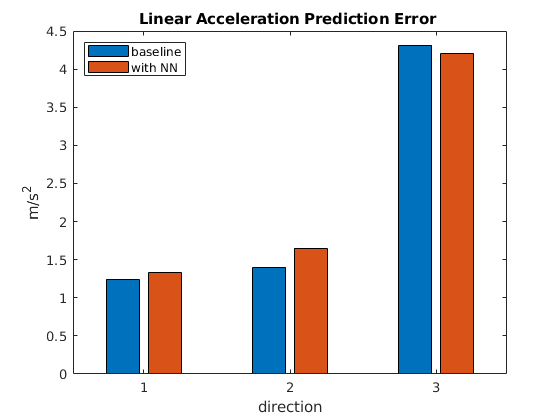

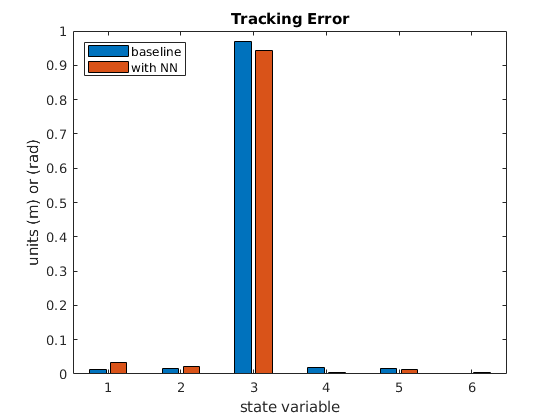

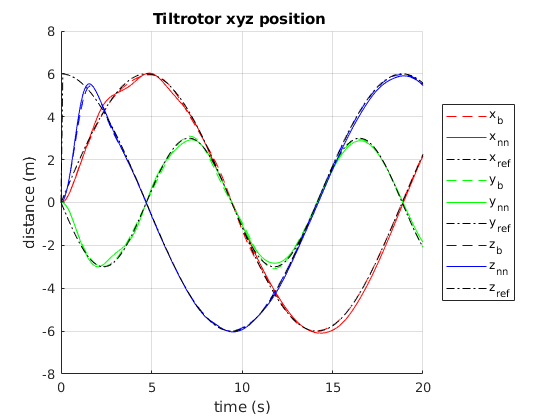

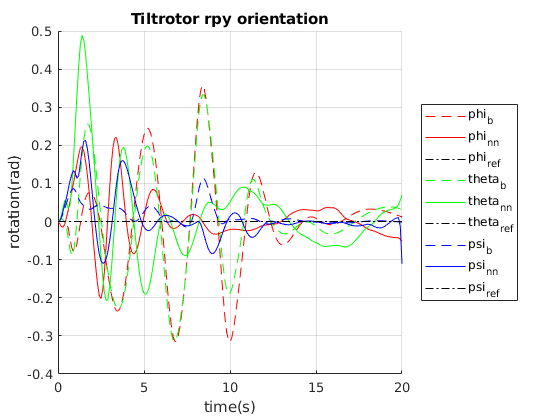

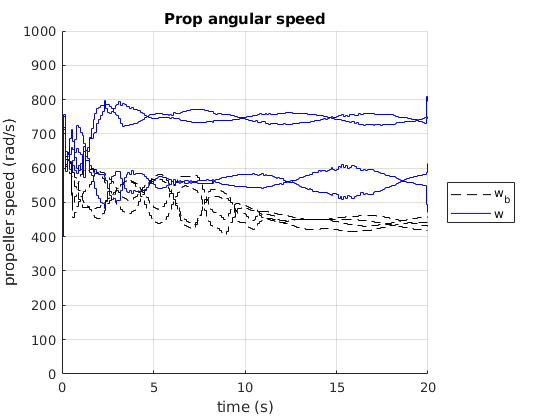

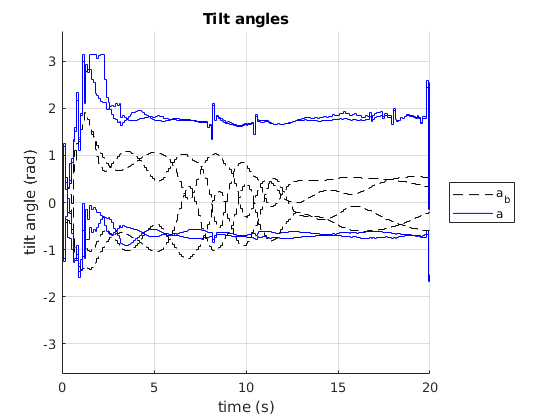

%append yrefHistory sHistory xHistory uHistory xpredHistory xdotHistory xdotpredHistory xdotnnpredHistory elapsed_times costs to data 
%           12          20      12       8         12           12          12                 12             1           1  

%% Baseline_results:
% 1-804: no_dist
%805-1608: const
%1609-2412: sigmoid
%2413:3216: ge
baseline_results=load('sim_results_baselinempc_27_05').sim_data;
baseline_ge2dist_results = load('sim_results_mpcbaseline_gedist2_29_05.mat').sim_data;
baseline_noisedist_results = load('sim_results_mpcbaseline_noise_29_05.mat').sim_data;
baseline_modeldist_results = load('sim_results_mpcbaseline_model_29_05.mat').sim_data;

%% NN results all using predict
nodist_wnn = load('sim_results_mpcwnodistnet_nodist_usingpredict_05_06.mat').sim_data;
constdist_wnn = load('sim_results_mpcwconstdistnet_constdist_usingpredict_05_06.mat').sim_data;
ge1dist_wnn = load('sim_results_mpcwge1distnet_ge1dist_usingpredict_05_06.mat').sim_data;
ge2dist_wnn = load('sim_results_mpcwge2distnet_ge2dist_usingpredict_05_06.mat').sim_data;
sigmoid_wnn = load('sim_results_mpcwsigmoiddistnet_sigmoiddist_usingpredict_05_06').sim_data;
modeldist_wnn = load('sim_results_mpcwmodeldistnet_modeldist_usingpredict_05_06.mat').sim_data;
noisedist_wnn = load('sim_results_mpcwmodeldistnet_noisedist_usingpredict_05_06.mat').sim_data;


%prediction errors [baseline,wnn]
prederrs = [];

%costs [baseline,wnn]
costs=[];

%tracking errors [baseline,wnn]
trackerrs =[];

%% Test trajectories 

%no
nodist_baseline_test = baseline_results(1:201,:);
nodist_wnn_test = nodist_wnn(1:201,:);
[prederrs,trackerrs,costs] = analyse(nodist_baseline_test,nodist_wnn_test,prederrs,trackerrs,costs);

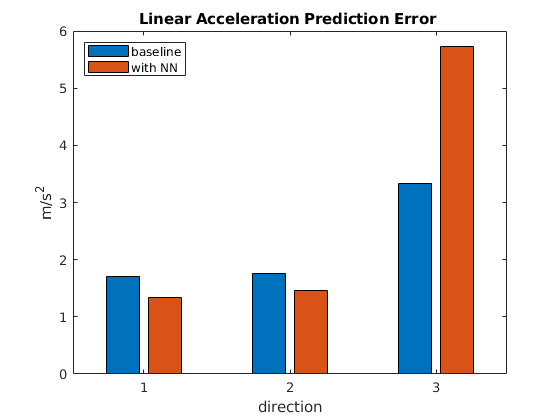

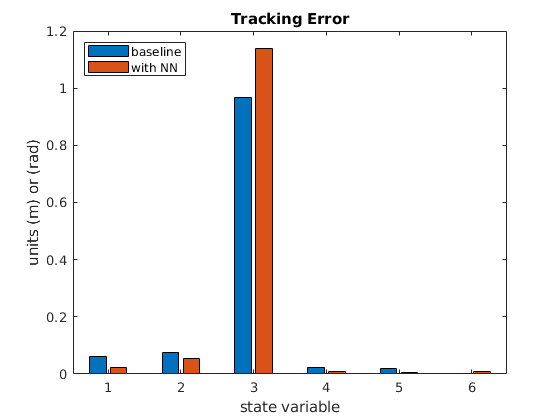

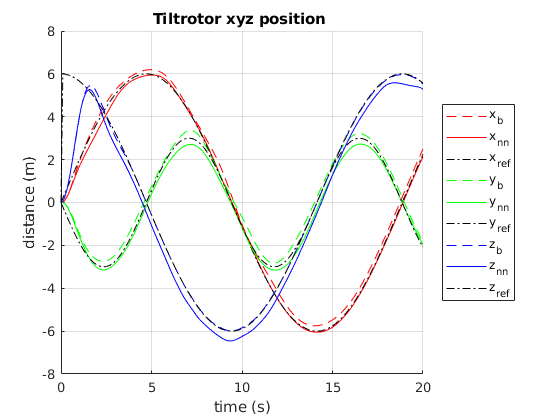

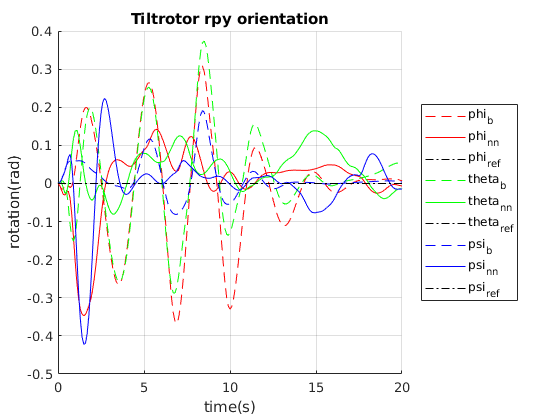

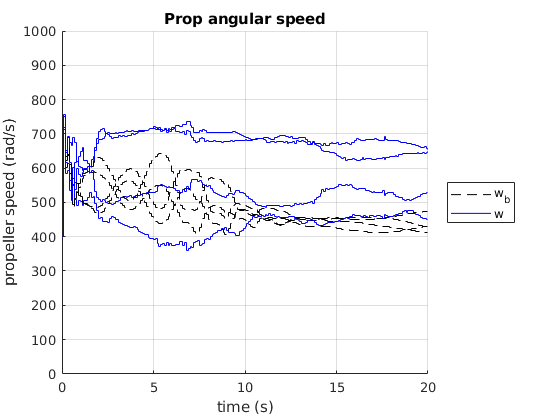

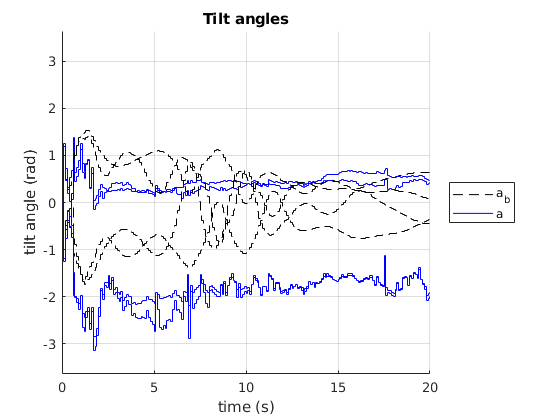


%const
constdist_baseline_test = baseline_results(805:1005,:);
constdist_wnn_test = constdist_wnn(1:201,:);
[prederrs,trackerrs,costs] = analyse(constdist_baseline_test,constdist_wnn_test,prederrs,trackerrs,costs);

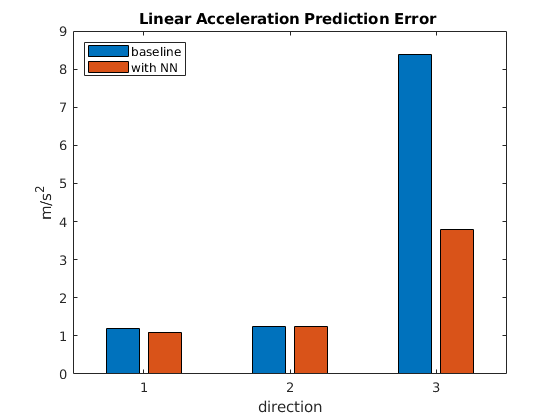

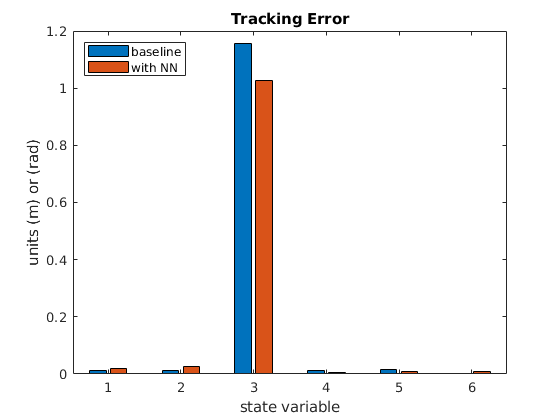

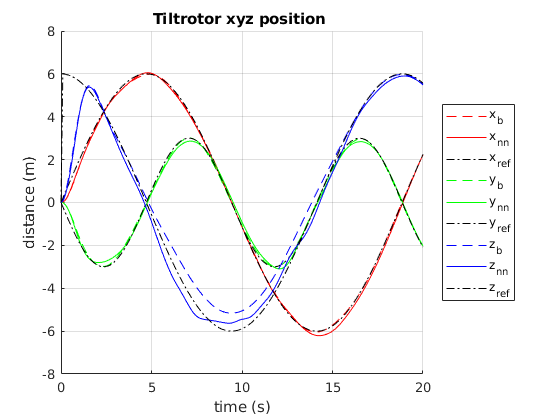

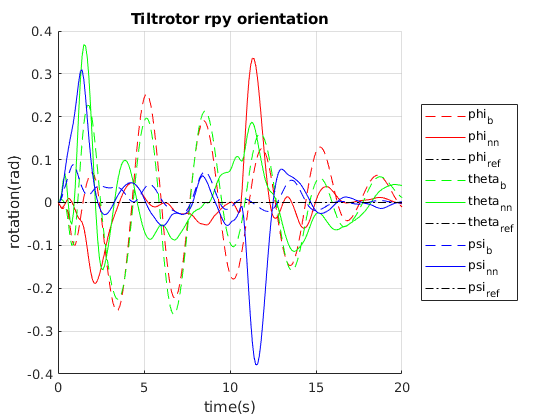

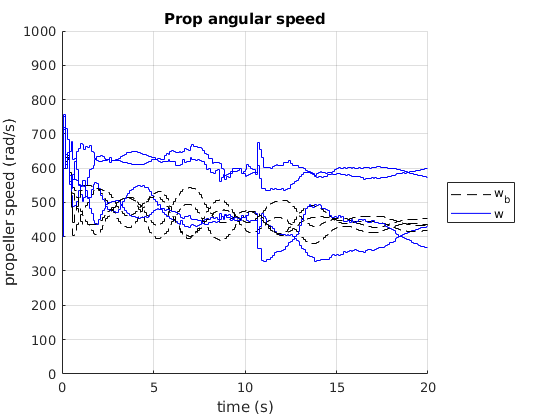

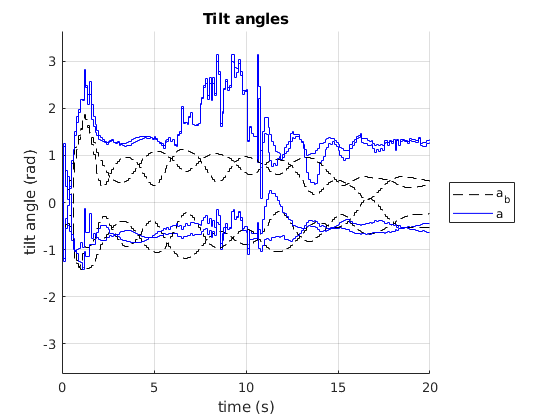


%ge1
gedist_baseline_test =baseline_results(2413:2613,:);
gedist_wnn_test = ge1dist_wnn(1:201,:);
[prederrs,trackerrs,costs] = analyse(gedist_baseline_test,gedist_wnn_test,prederrs,trackerrs,costs);

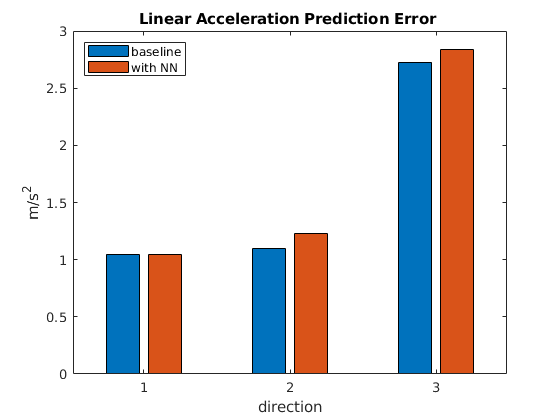

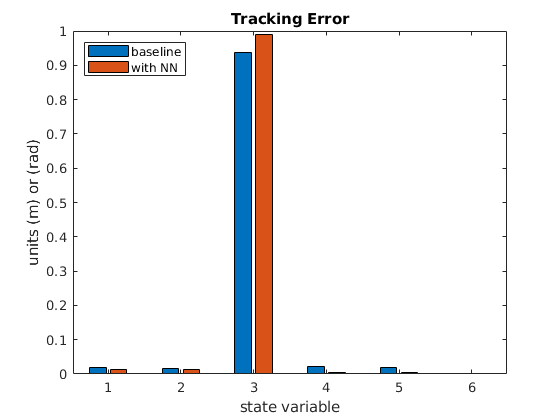

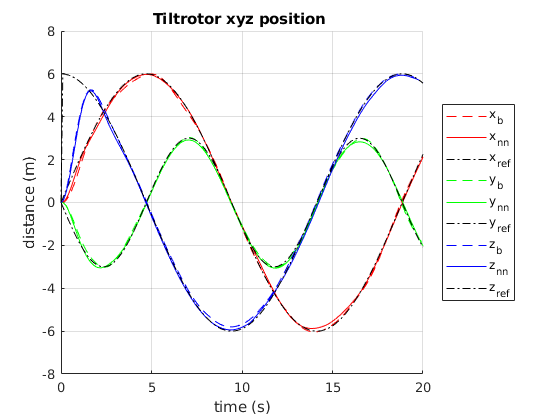

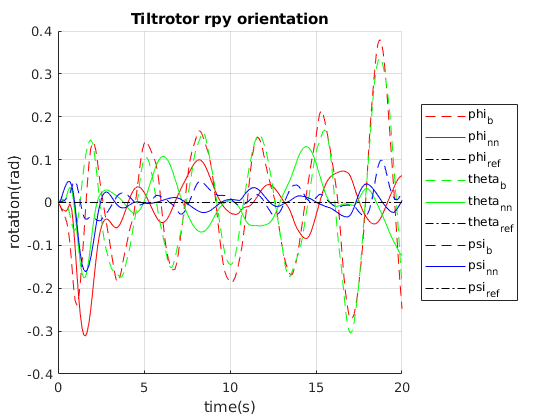

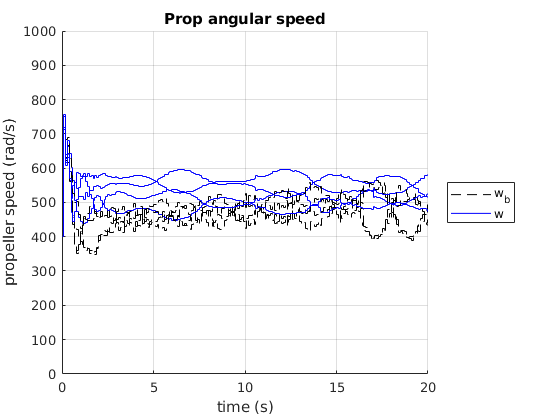

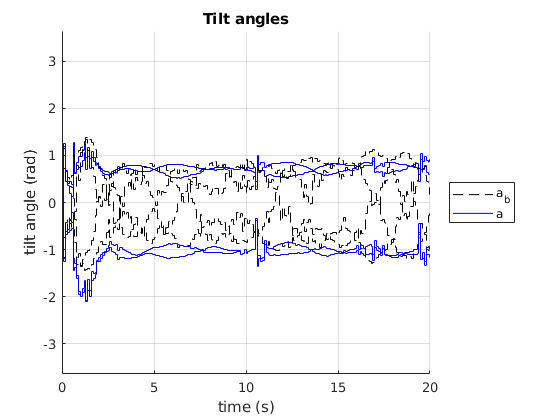


%ge2
ge2dist_baseline_test = baseline_ge2dist_results(1:201,:);
ge2dist_wnn_test = ge2dist_wnn(1:201,:);
[prederrs,trackerrs,costs] = analyse(ge2dist_baseline_test,ge2dist_wnn_test,prederrs,trackerrs,costs);

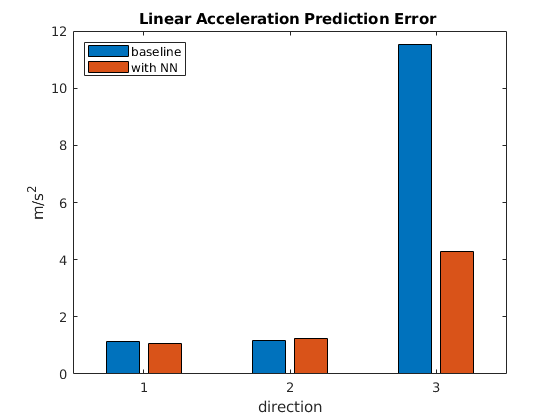

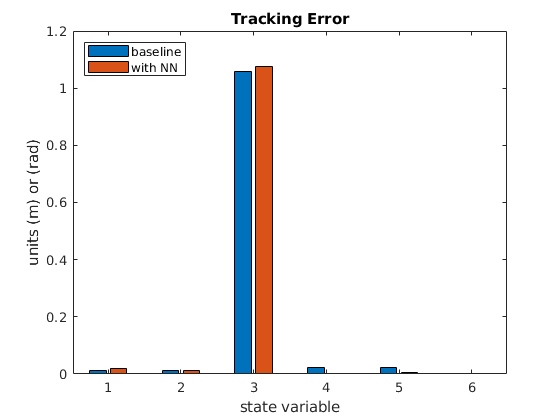

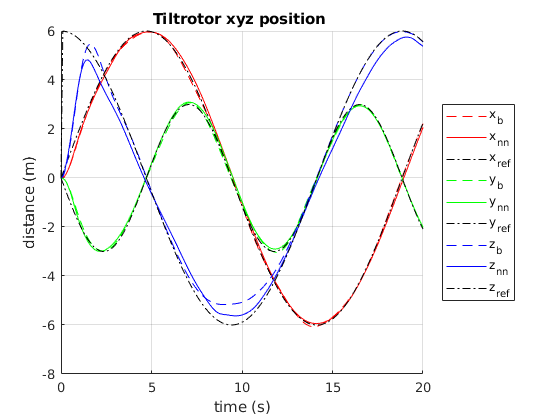

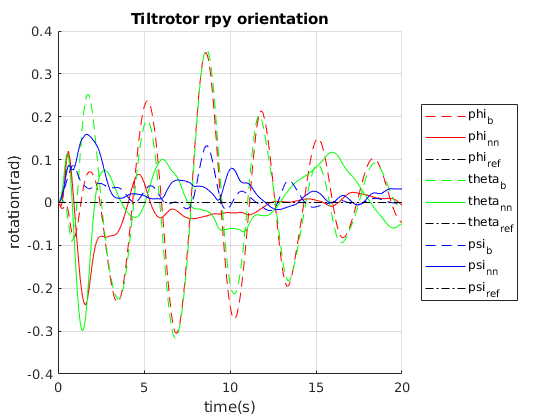

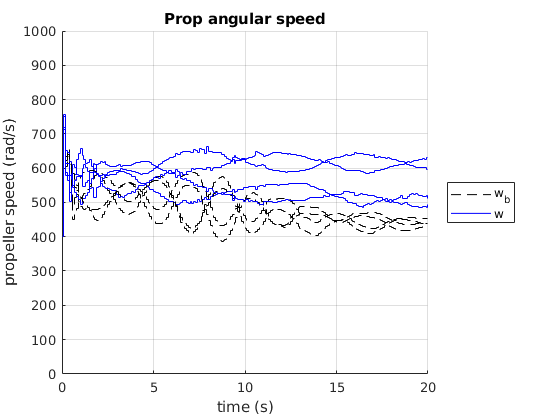

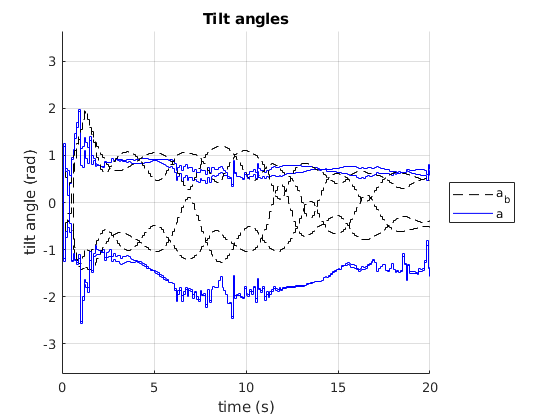


%sigmoid
sigmoid_baseline_test = baseline_results(1609:1809,:);
sigmoid_wnn_test = sigmoid_wnn(1:201,:);
[prederrs,trackerrs,costs] = analyse(sigmoid_baseline_test,sigmoid_wnn_test,prederrs,trackerrs,costs);

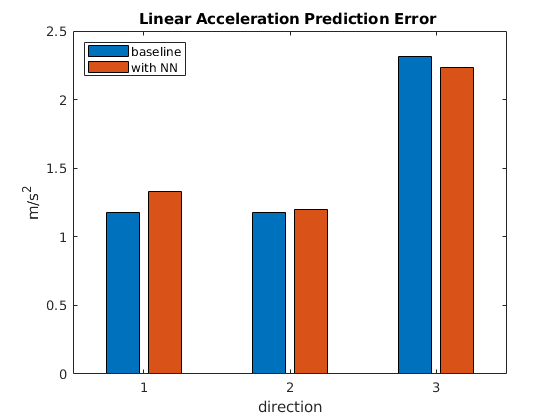

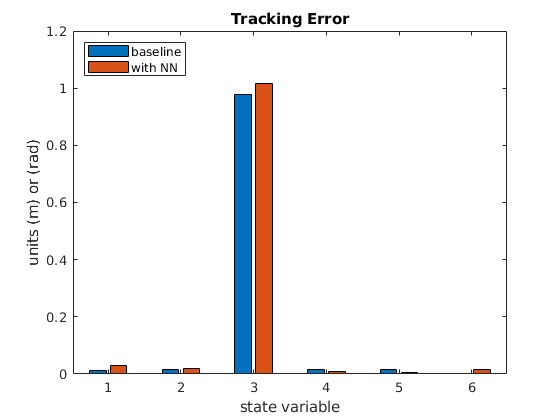

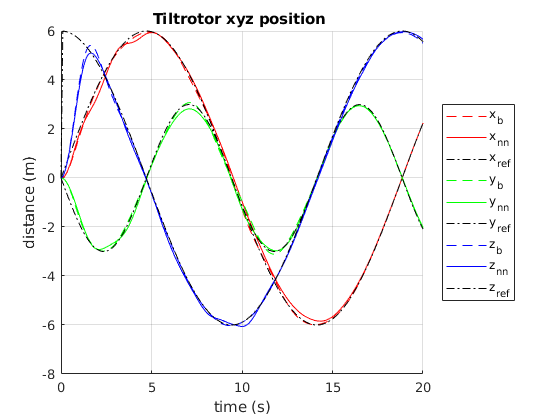

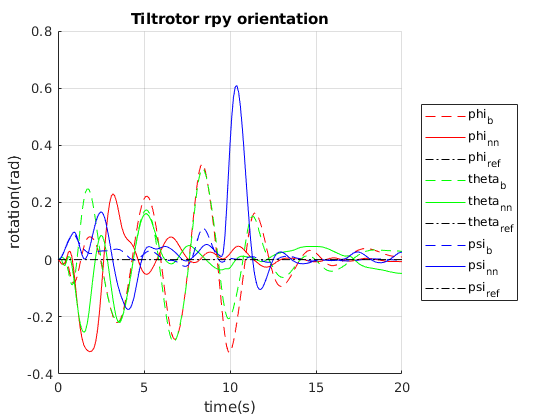

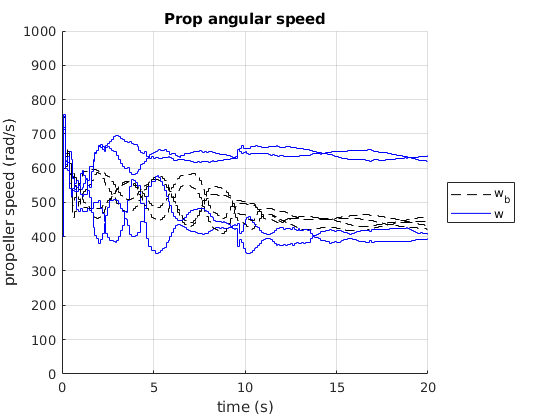

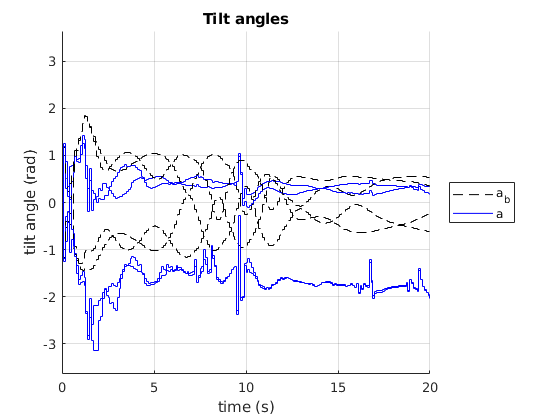


%model
modeldist_baseline_test = baseline_modeldist_results(1:201,:);
modeldist_wnn_test = modeldist_wnn(1:201,:);
[prederrs,trackerrs,costs] = analyse(modeldist_baseline_test,modeldist_wnn_test,prederrs,trackerrs,costs);

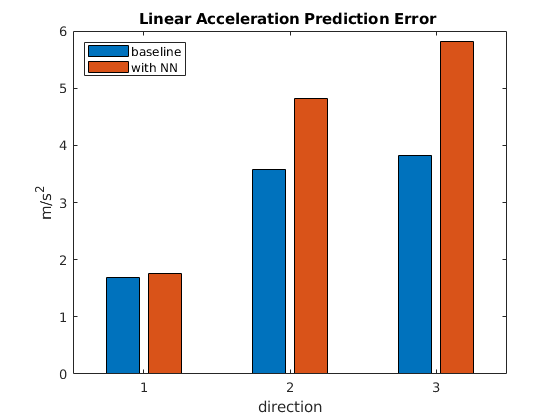

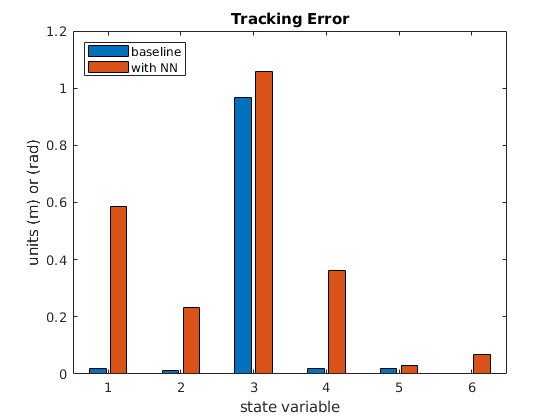

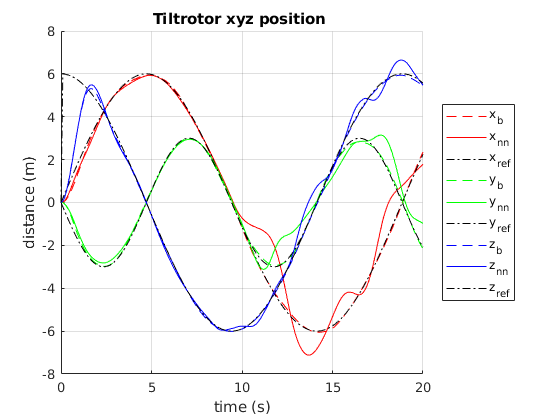

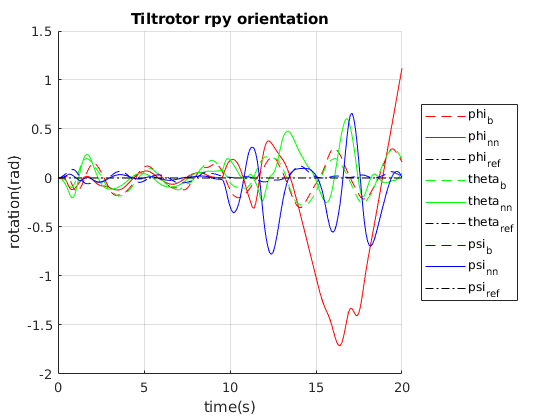

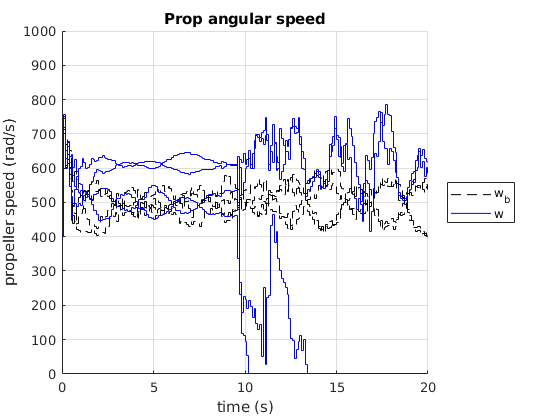

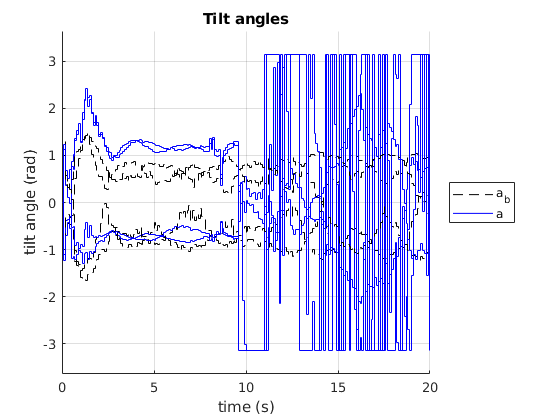


%noise
noisedist_baseline_test = baseline_noisedist_results(1:201,:);
noisedist_wnn_test = noisedist_wnn(1:201,:);
[prederrs,trackerrs,costs] = analyse(noisedist_baseline_test,noisedist_wnn_test,prederrs,trackerrs,costs);

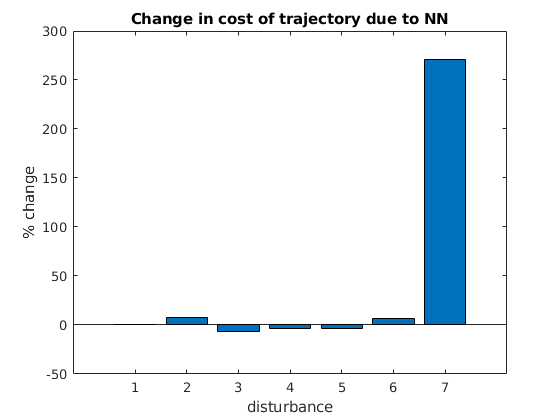


figure;
%x = categorical({'Baseline','with NN'});
bar(costs);
title('Change in cost of trajectory due to NN');
ylabel('% change');
xlabel('disturbance')
saveas(gcf,'coststest.png')

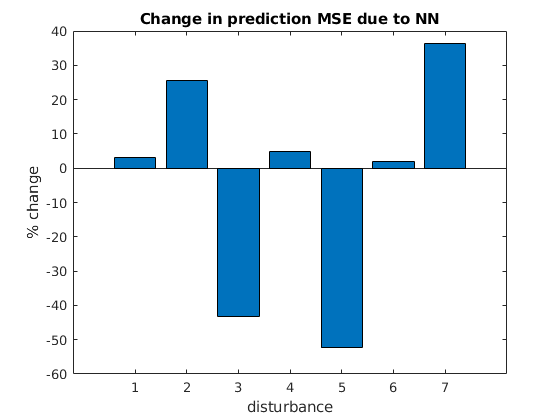


figure;
%x = categorical({'Baseline','with NN'});
bar(prederrs);
title('Change in prediction MSE due to NN');
ylabel('% change');
xlabel('disturbance')
saveas(gcf,'prederrtest.png')

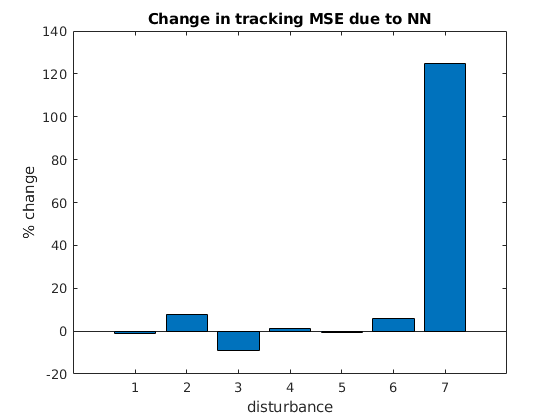


figure;
%x = categorical({'Baseline','with NN'});
bar(trackerrs);
title('Change in tracking MSE due to NN');
ylabel('% change');
xlabel('disturbance')
saveas(gcf,'trackerrtest.png')

## Train trajectories

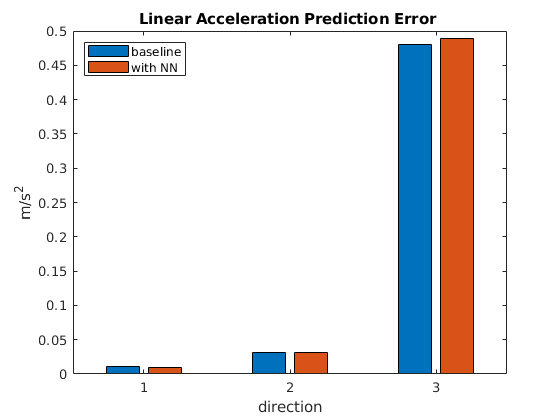

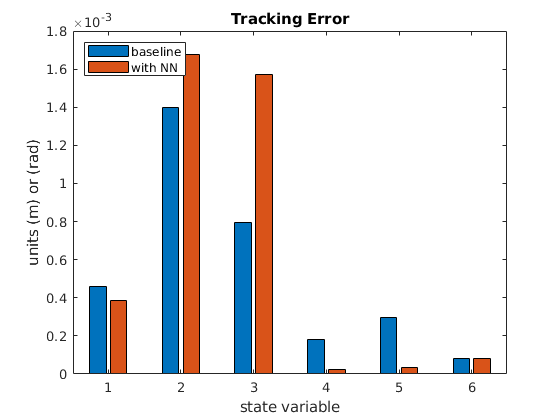

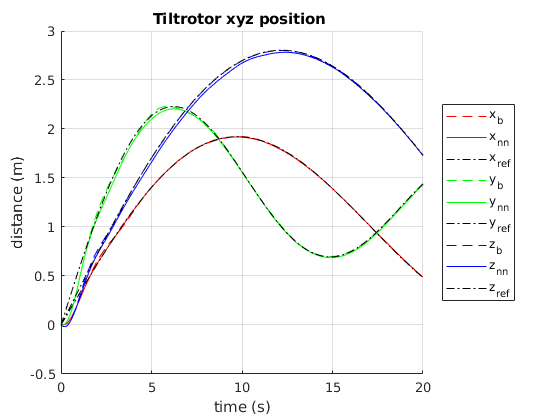

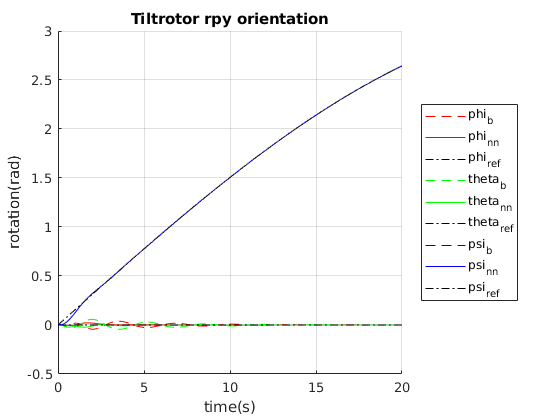

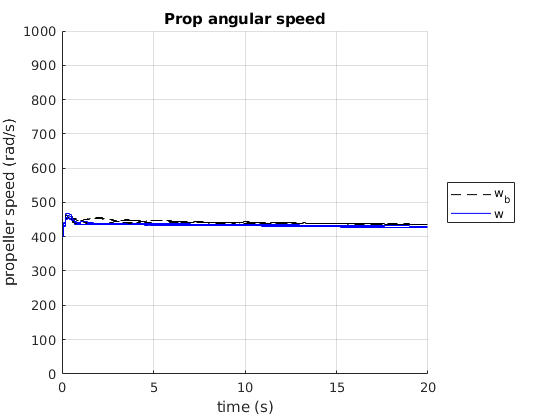

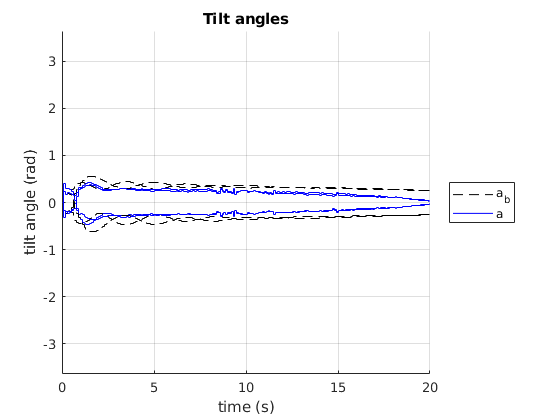

%prediction errors [baseline,wnn]
prederrs = [];

%costs [baseline,wnn]
costs=[];

%tracking errors [baseline,wnn]
trackerrs =[];

%no
nodist_baseline = baseline_results(202:402,:);
nodist_wnn = nodist_wnn(202:402,:);
[prederrs,trackerrs,costs] = analyse(nodist_baseline,nodist_wnn,prederrs,trackerrs,costs);

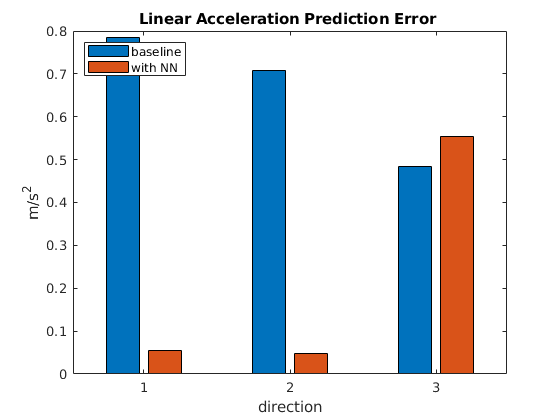

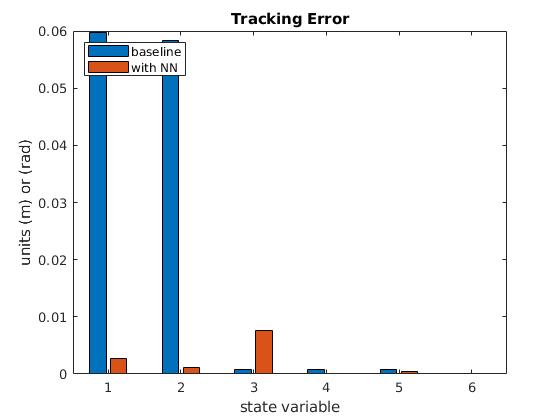

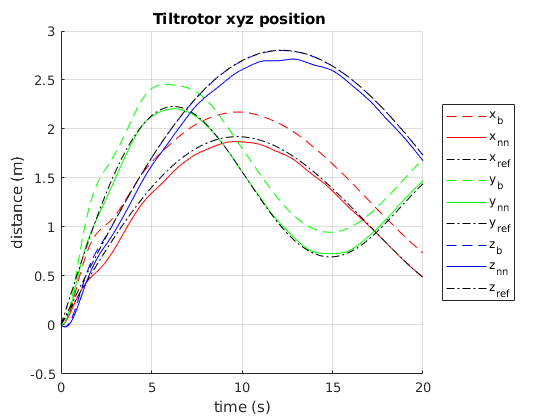

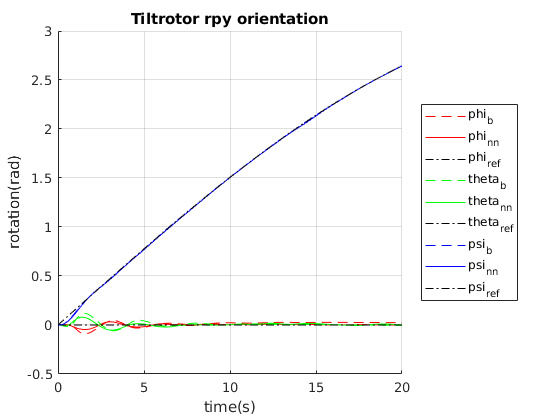

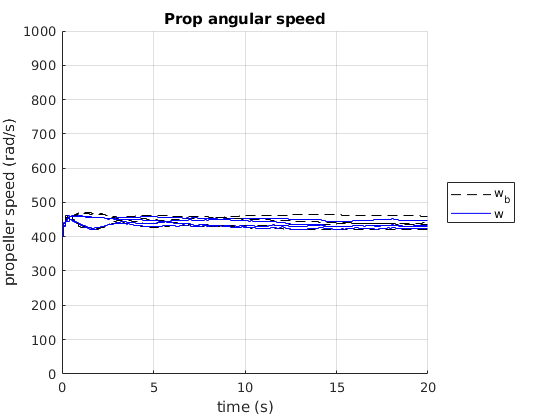

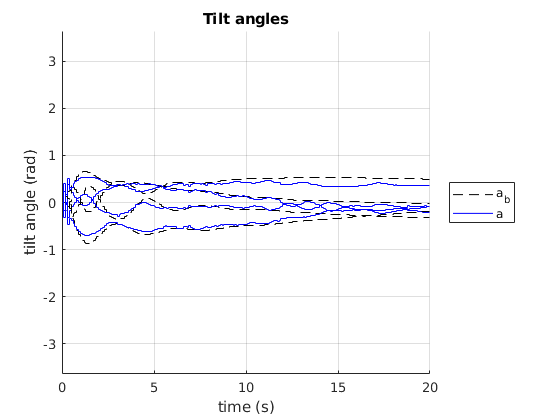



%const
constdist_baseline = baseline_results(1006:1206,:); 
constdist_wnn = constdist_wnn(202:402,:);
[prederrs,trackerrs,costs] = analyse(constdist_baseline,constdist_wnn,prederrs,trackerrs,costs);

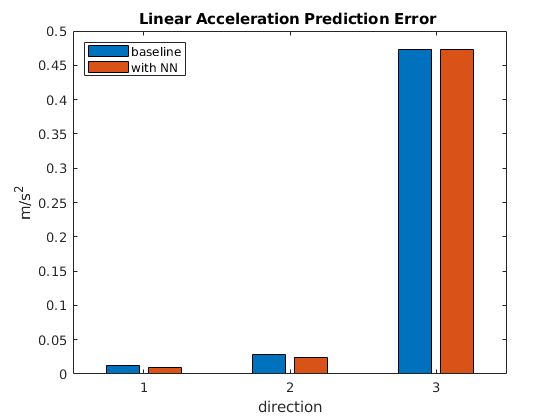

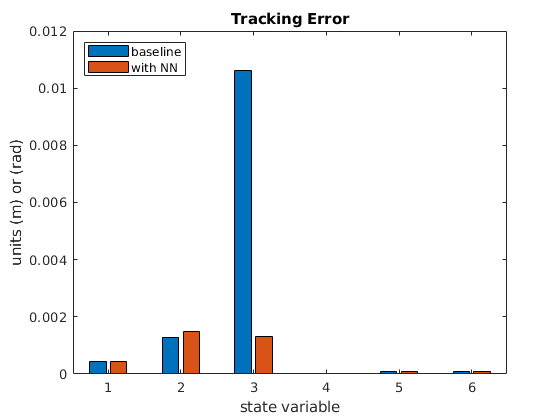

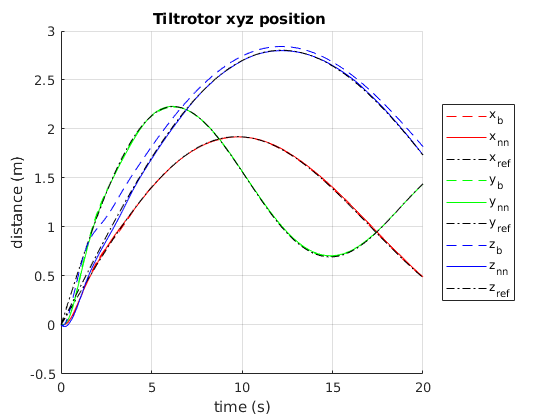

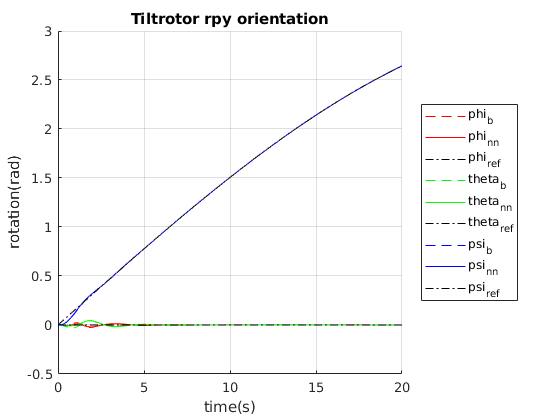

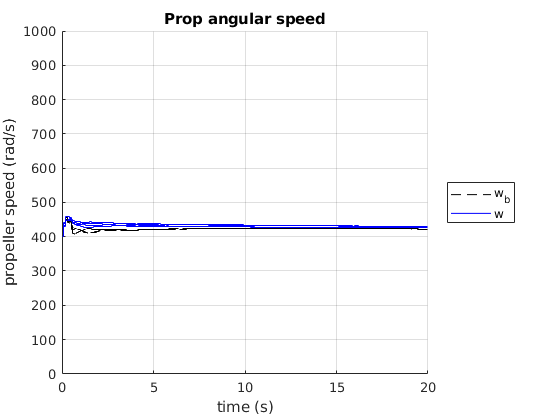

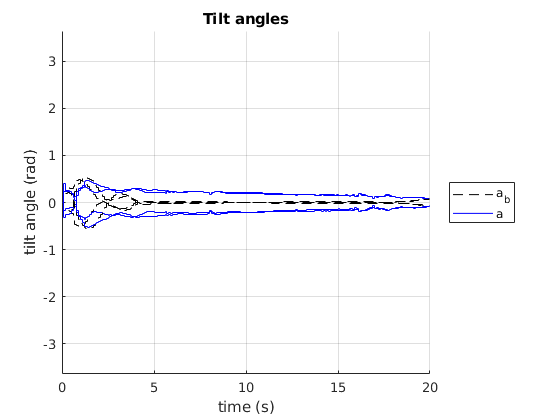


%ge1
gedist_baseline = baseline_results(2614:2814,:);
ge1dist_wnn = ge1dist_wnn(202:402,:);
[prederrs,trackerrs,costs] = analyse(gedist_baseline,ge1dist_wnn,prederrs,trackerrs,costs);

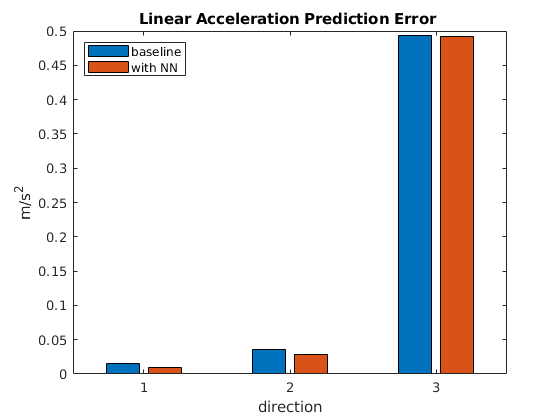

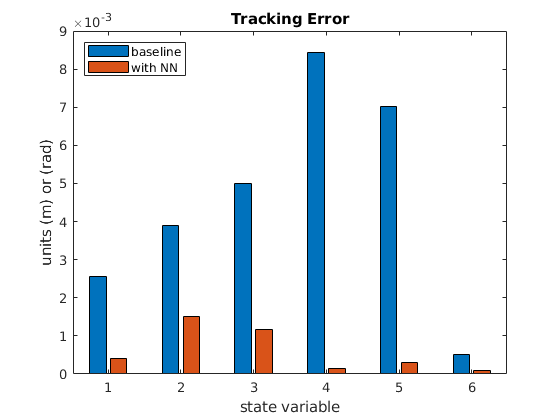

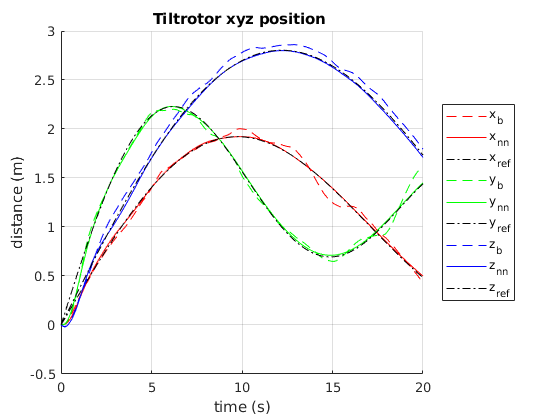

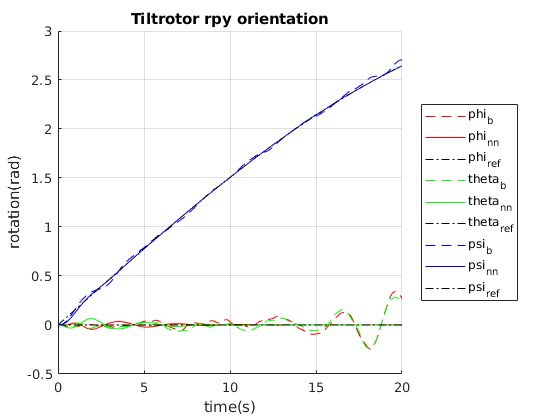

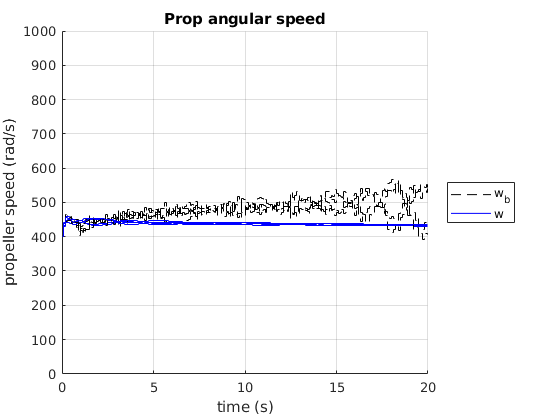

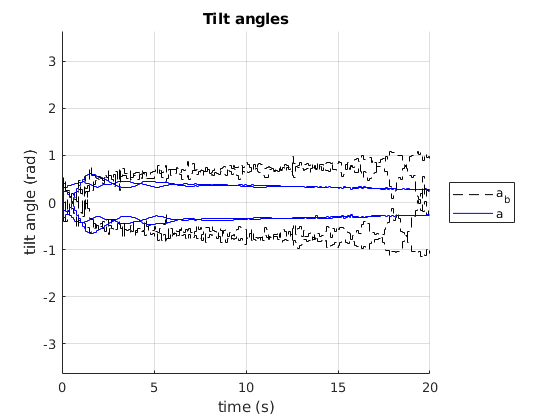


%ge2
ge2dist_baseline = baseline_ge2dist_results(202:402,:);
ge2dist_wnn = ge2dist_wnn(202:402,:);
[prederrs,trackerrs,costs] = analyse(ge2dist_baseline,ge2dist_wnn,prederrs,trackerrs,costs);

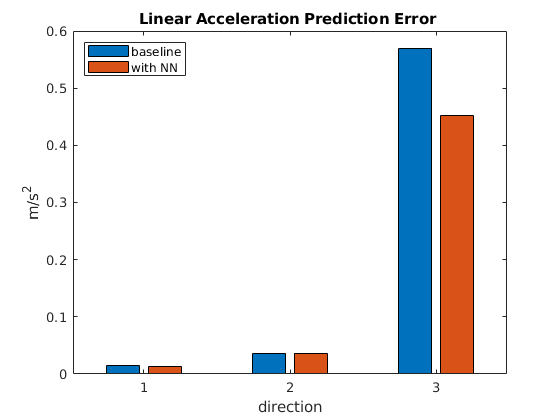

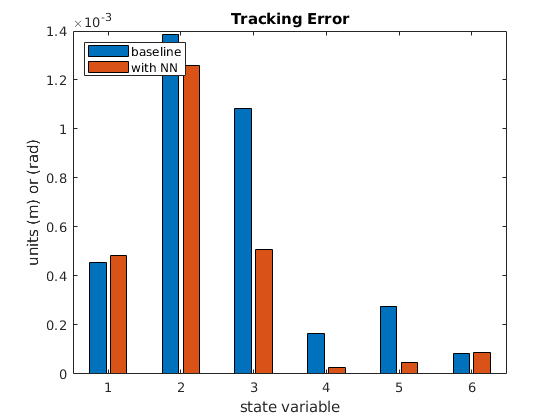

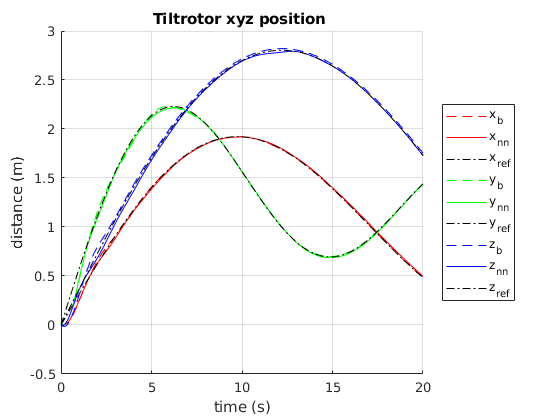

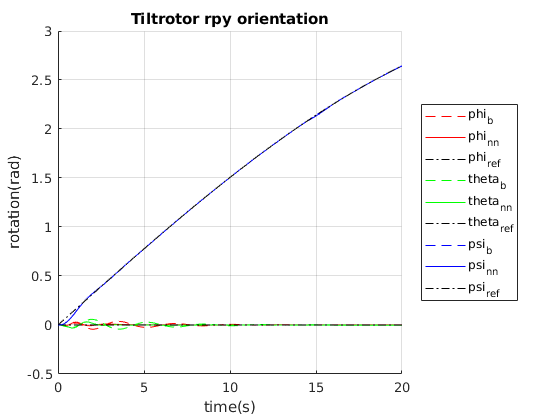

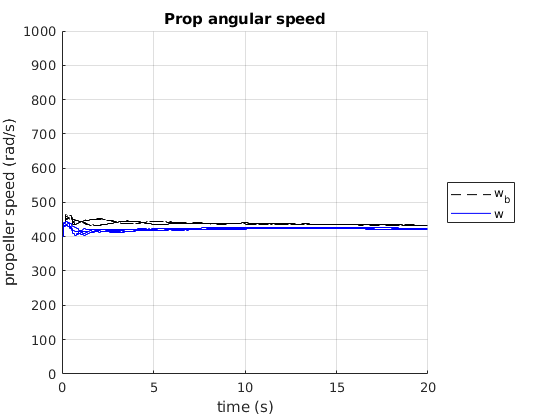

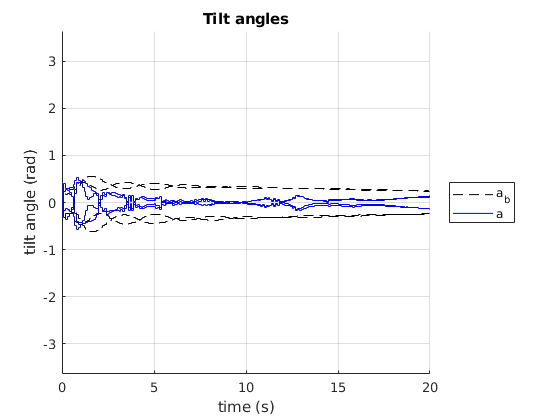


%sigmoid
sigmoid_baseline = baseline_results(1810:2010,:);
sigmoid_wnn = sigmoid_wnn(202:402,:);
[prederrs,trackerrs,costs] = analyse(sigmoid_baseline,sigmoid_wnn,prederrs,trackerrs,costs);

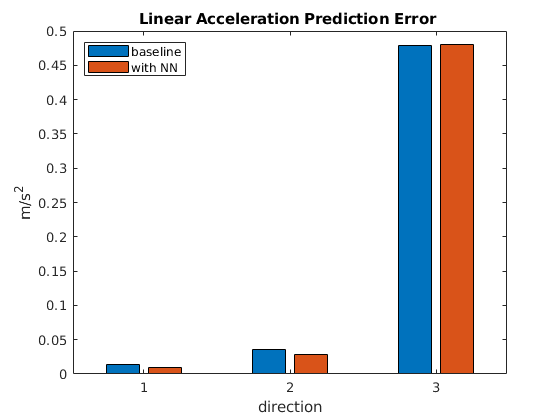

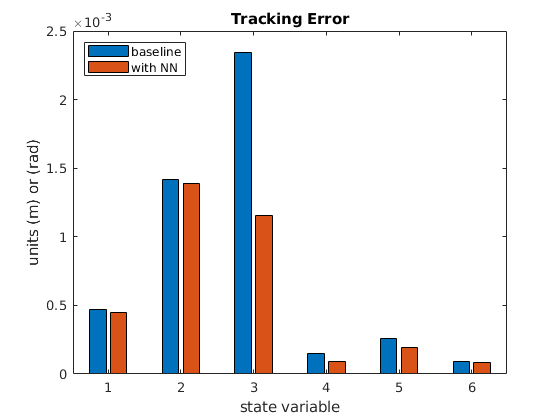

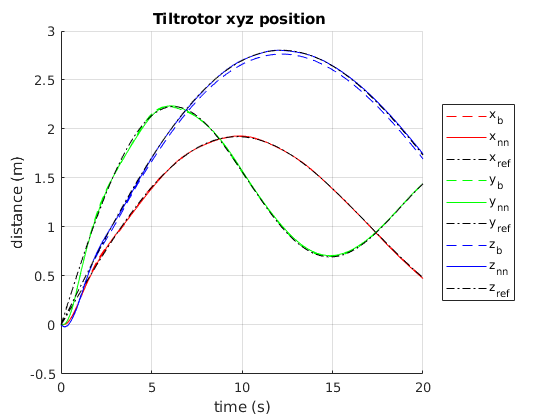

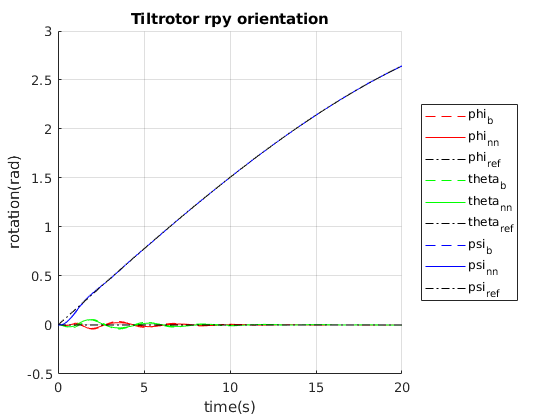

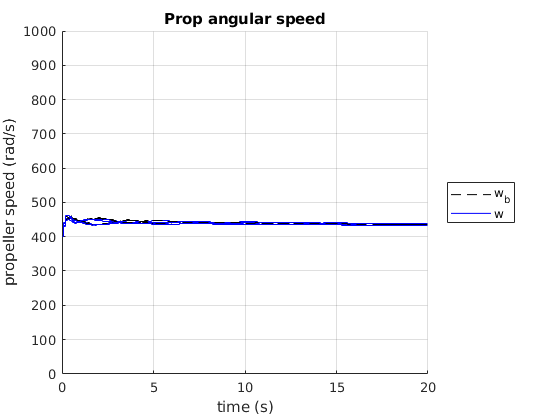

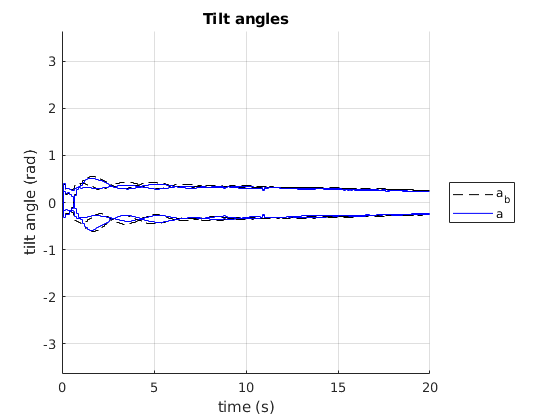


%model
modeldist_baseline= baseline_modeldist_results(202:402,:);
modeldist_wnn = modeldist_wnn(202:402,:);
[prederrs,trackerrs,costs] = analyse(modeldist_baseline,modeldist_wnn,prederrs,trackerrs,costs);

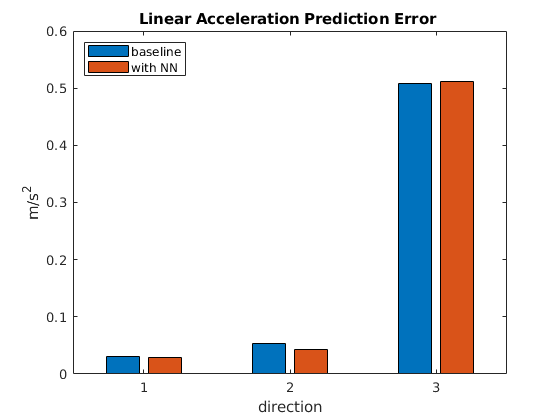

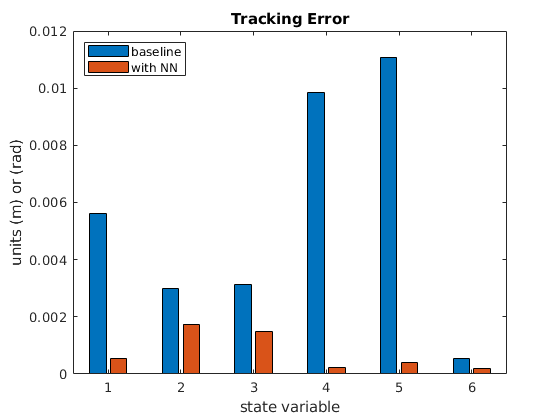

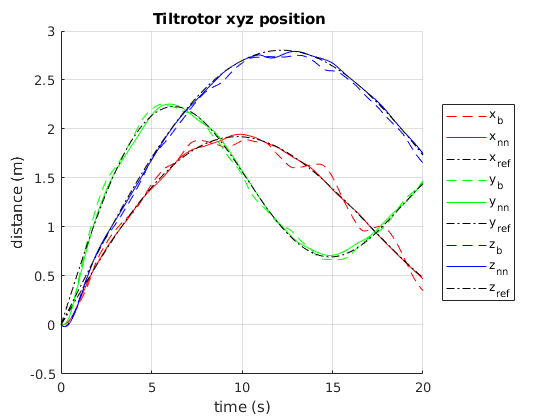

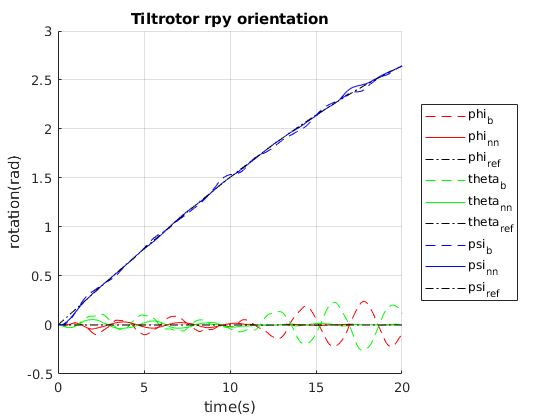

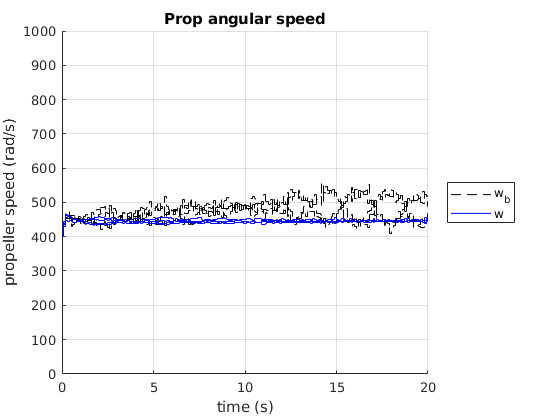

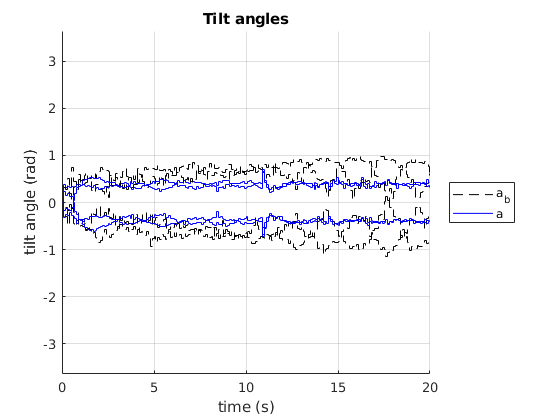


%noise
noisedist_baseline = baseline_noisedist_results(202:402,:);
noisedist_wnn = noisedist_wnn(202:402,:);
[prederrs,trackerrs,costs] = analyse(noisedist_baseline,noisedist_wnn,prederrs,trackerrs,costs);

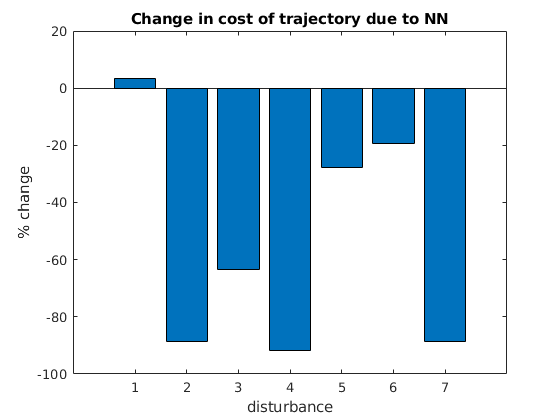


figure;
%x = categorical({'Baseline','with NN'});
bar(costs);
title('Change in cost of trajectory due to NN');
ylabel('% change');
xlabel('disturbance')
saveas(gcf,'coststrain.png')

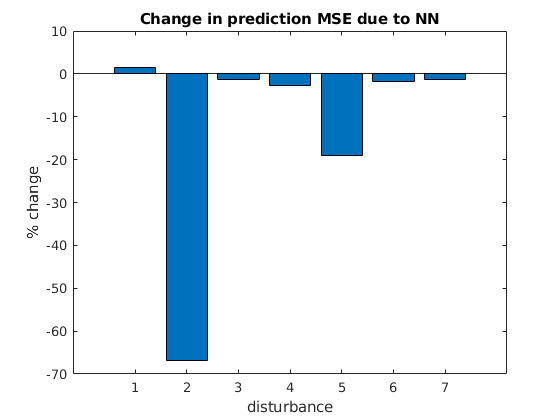


figure;
%x = categorical({'Baseline','with NN'});
bar(prederrs);
title('Change in prediction MSE due to NN');
ylabel('% change');
xlabel('disturbance')
saveas(gcf,'prederrtrain.png')

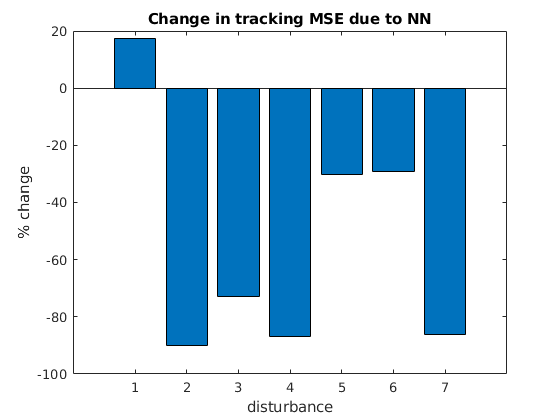


figure;
%x = categorical({'Baseline','with NN'});
bar(trackerrs);
title('Change in tracking MSE due to NN');
ylabel('% change');
xlabel('disturbance')
saveas(gcf,'trackerrtrain.png')